% read in data

%data will be used from 4 young mice and 4 old mice

% reading in data for young mouse 1
genetableY1 = readtable('YoungM1.txt');
genelist = genetableY1(:,1);    %list containing gene names
genelist = table2array(genelist);
genetableY1(:,1) = [];          % processing of txt file
genetableY1 = table2array(genetableY1);

% reading in data for young mouse 2
genetableY2 = readtable('YoungM2.txt');
genetableY2(:,1) = [];          % processing of txt file
genetableY2 = table2array(genetableY2);

% reading in data for young mouse 3
genetableY3 = readtable('YoungM3.txt');
genetableY3(:,1) = [];          % processing of txt file
genetableY3 = table2array(genetableY3);

% reading in data for young mouse 4
genetableY4 = readtable('YoungM4.txt');
genetableY4(:,1) = [];          % processing of txt file
genetableY4 = table2array(genetableY4);



% combine data to create 1 young mouse dataset
genetableY = cat(2, genetableY1, genetableY2, genetableY3, genetableY4);


%preparing data for old mice samples

%mouse 1
genetableO1 = readmatrix('OldM1.txt');
genetableO1(:,1) = [];

% reading in data for young mouse 2
genetableO2 = readmatrix('OldM2.txt');
genetableO2(:,1) = [];

% reading in data for young mouse 3
genetableO3 = readmatrix('OldM3.txt');
genetableO3(:,1) = [];


% reading in data for young mouse 4
genetableO4 = readmatrix('OldM4.txt');
genetableO4(:,1) = [];

%combining data from each sample
genetableO = cat(2, genetableO1, genetableO2, genetableO3, genetableO4);

%matrix of both Young and Old samples
genetableBoth = cat(2, genetableY,genetableO);

% Use cell-type marker genes defined in paper to identify cell types

%oligodendrocyte precursor (OPC)
OPCgene = find(strcmp(genelist,'Pdgfra'));
OPCindY = find(genetableY(OPCgene,:)>1);
OPCindO = find(genetableO(OPCgene,:)>1);

OPCindY1 = find(genetableY1(OPCgene,:)>1);
OPCindO1 = find(genetableO1(OPCgene,:)>1);

OPCindY2 = find(genetableY2(OPCgene,:)>1);
OPCindO2 = find(genetableO2(OPCgene,:)>1);

OPCindY3 = find(genetableY3(OPCgene,:)>1);
OPCindO3 = find(genetableO3(OPCgene,:)>1);

OPCindY4 = find(genetableY4(OPCgene,:)>1);
OPCindO4 = find(genetableO4(OPCgene,:)>1);

%oligodendrocyte (OLG)
OLGgene = find(strcmp(genelist,'Cldn11'));
OLGindY = find(genetableY(OLGgene,:)>1);
OLGindO = find(genetableO(OLGgene,:)>1);

%astrocytes (ASC)
ASCgene = find(strcmp(genelist,'Gja1'));
ASCindY = find(genetableY(ASCgene,:)>1.75);
ASCindO = find(genetableO(ASCgene,:)>1.75);

%mature neurons (mNEUR)
mNEURgene = find(strcmp(genelist,'Syt1'));
mNEURindY = find(genetableY(mNEURgene,:)>1);
mNEURindO = find(genetableO(mNEURgene,:)>1);

%endothelial cells (EC)
ECgene = find(strcmp(genelist,'Cldn5'));
ECindY = find(genetableY(ECgene,:)>1.25);
ECindO = find(genetableO(ECgene,:)>1.25);

ECindY1 = find(genetableY1(ECgene,:)>1);
ECindO1 = find(genetableO1(ECgene,:)>1);

ECindY2 = find(genetableY2(ECgene,:)>1);
ECindO2 = find(genetableO2(ECgene,:)>1);

ECindY3 = find(genetableY3(ECgene,:)>1);
ECindO3 = find(genetableO3(ECgene,:)>1);

ECindY4 = find(genetableY4(ECgene,:)>1);
ECindO4 = find(genetableO4(ECgene,:)>1);

%microglia (MG)
MGgene = find(strcmp(genelist,'Tmem119'));
MGindY = find(genetableY(MGgene,:)>1);
MGindO = find(genetableO(MGgene,:)>1);
MGY = genetableY(:,MGindY);



tsne = tsne(genetableBoth', "Algorithm","barneshut", "NumPCAComponents",20);

Unrecognized function or variable 'genetable'.

Index in position 2 exceeds array bounds (must not exceed 1).

%tsneOPCO1 = tsne(genetableO1(:,OPCindO1)', "Algorithm","barneshut", "NumPCAComponents",50);

plot(tsne(:,1),tsne(:,2),'k.')

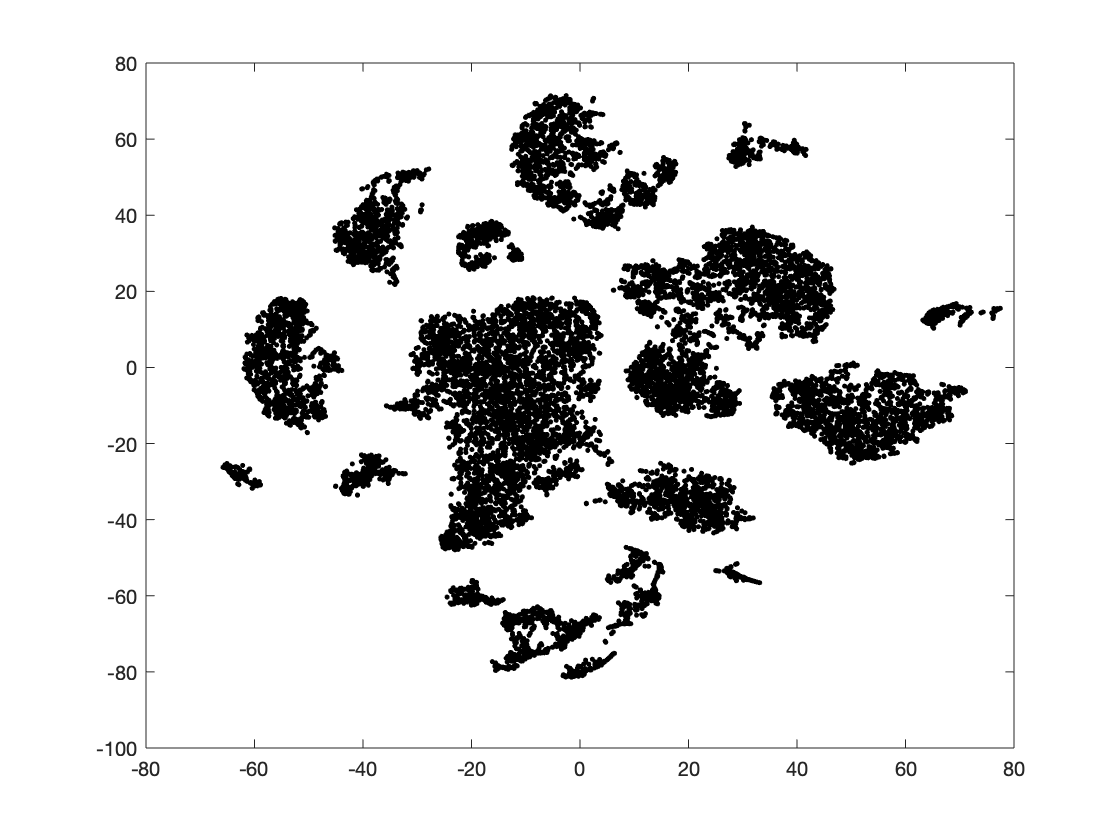

hold on
plot(tsne(OPCindO,1),tsne(OPCindO,2), 'r.')
plot(tsne(OPCindY,1),tsne(OPCindY,2),'r.')


plot(tsne(MGindO,1),tsne(MGindO,2),'b.')
plot(tsne(MGindY,1),tsne(MGindY,2),'b.')

plot(tsne(OLGindO,1),tsne(OLGindO,2),'g.')
plot(tsne(OLGindY,1),tsne(OLGindY,2),'g.')

plot(tsne(ASCindO,1),tsne(ASCindO,2),'c.')
plot(tsne(ASCindY,1),tsne(ASCindY,2),'c.')

plot(tsne(mNEURindO,1),tsne(mNEURindO,2),'m.')
plot(tsne(mNEURindY,1),tsne(mNEURindY,2),'m.')

plot(tsne(ECindO,1),tsne(ECindO,2),'y.')
plot(tsne(ECindY,1),tsne(ECindY,2),'y.')



ylabel('t-SNE_2')
xlabel('t-SNE_1')
legend('OPC', 'OLG', 'ASC', 'mNEUR', 'EC', 'MG')
title('t-SNE Plot of Young and Old Mouse Cells')
hold off

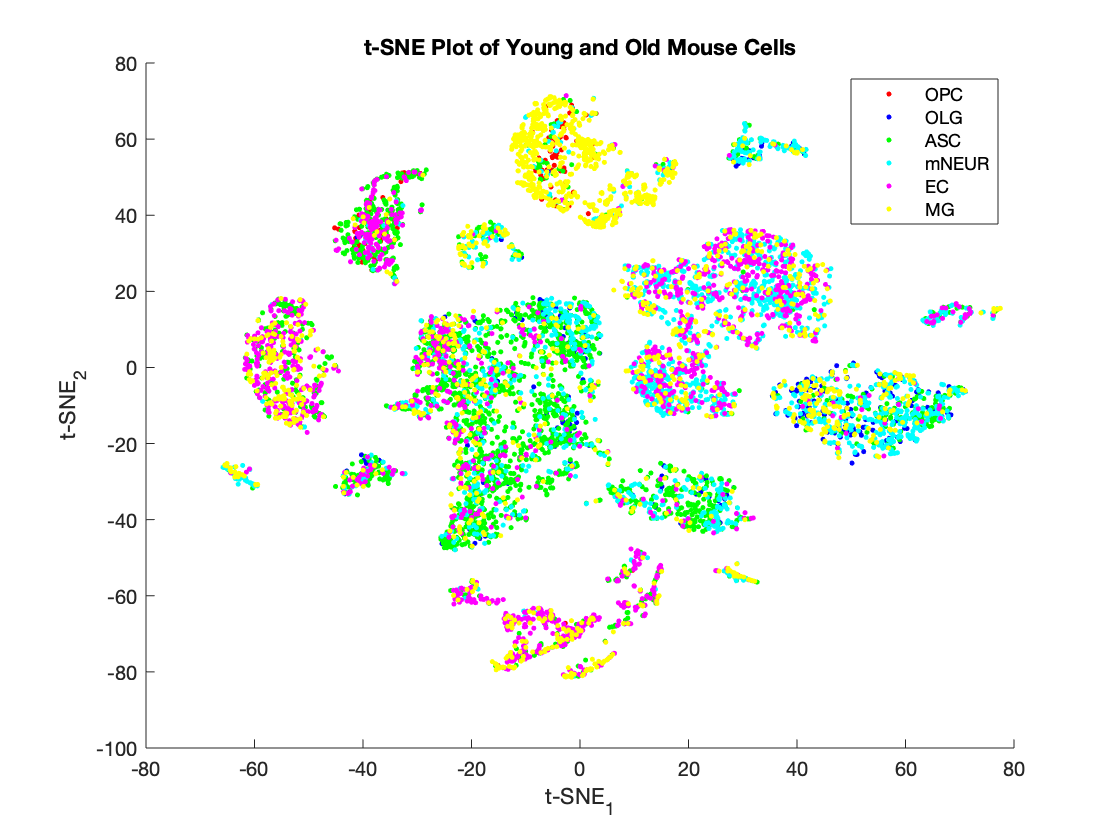


hold on
plot(tsne(OPCindY,1),tsne(OPCindY,2),'r.')
plot(tsne(MGindY,1),tsne(MGindY,2),'b.')

plot(tsne(OLGindY,1),tsne(OLGindY,2),'g.')
plot(tsne(ASCindY,1),tsne(ASCindY,2),'c.')
plot(tsne(mNEURindY,1),tsne(mNEURindY,2),'m.')
plot(tsne(ECindY,1),tsne(ECindY,2),'y.')
hold off
ylabel('t-SNE_2')
xlabel('t-SNE_1')
legend('OPC', 'OLG', 'ASC', 'mNEUR', 'EC', 'MG')
title('t-SNE Plot of Young Mouse Cells')

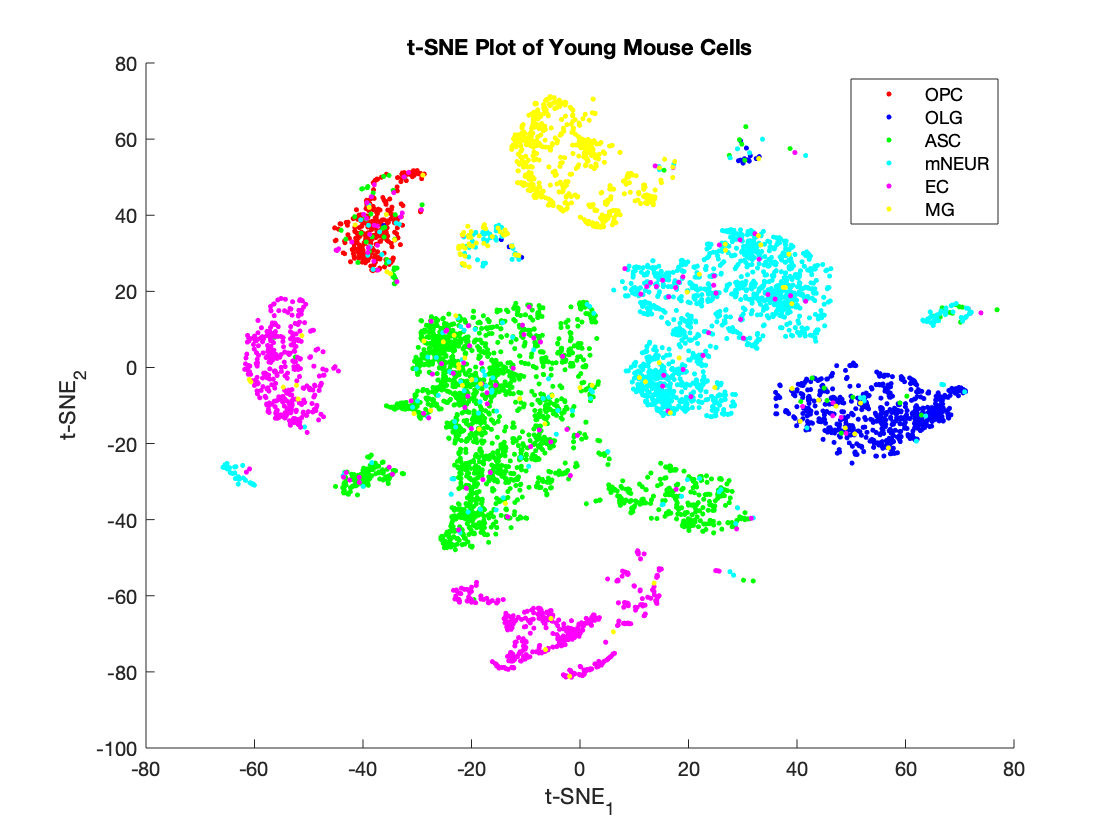


hold on
plot(tsne(OPCindO,1),tsne(OPCindO,2), 'r.')
plot(tsne(MGindO,1),tsne(MGindO,2),'b.')
plot(tsne(OLGindO,1),tsne(OLGindO,2),'g.')

plot(tsne(ASCindO,1),tsne(ASCindO,2),'c.')
plot(tsne(mNEURindO,1),tsne(mNEURindO,2),'m.')
plot(tsne(ECindO,1),tsne(ECindO,2),'y.')
hold off
ylabel('t-SNE_2')
xlabel('t-SNE_1')
legend('OPC', 'OLG', 'ASC', 'mNEUR', 'EC', 'MG')
title('t-SNE Plot of Old Mouse Cells')

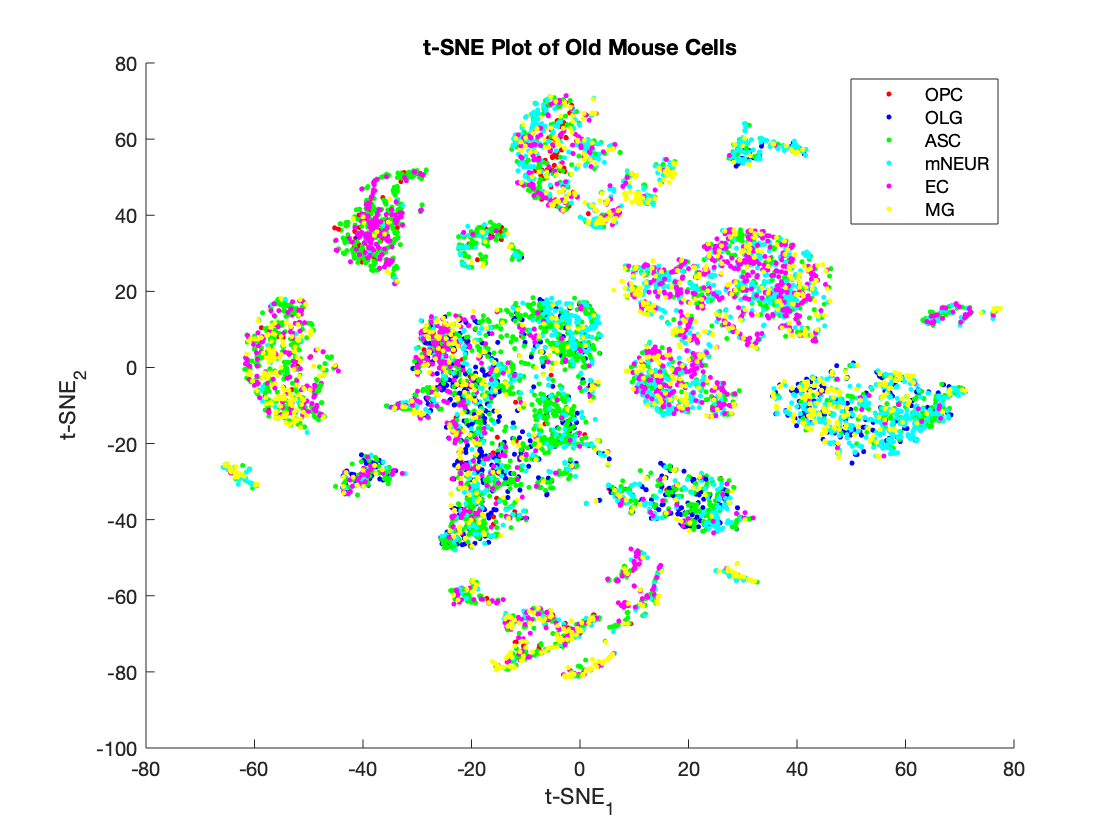

% analyze cellular composition across young and old groups

% first aggregate data/calculate cellular compositions
younghist = [length(OPCindY), length(OLGindY),length(ASCindY),length(mNEURindY),length(ECindY),length(MGindY)];
oldhist = [length(OPCindO), length(OLGindO),length(ASCindO),length(mNEURindO),length(ECindO),length(MGindO)];

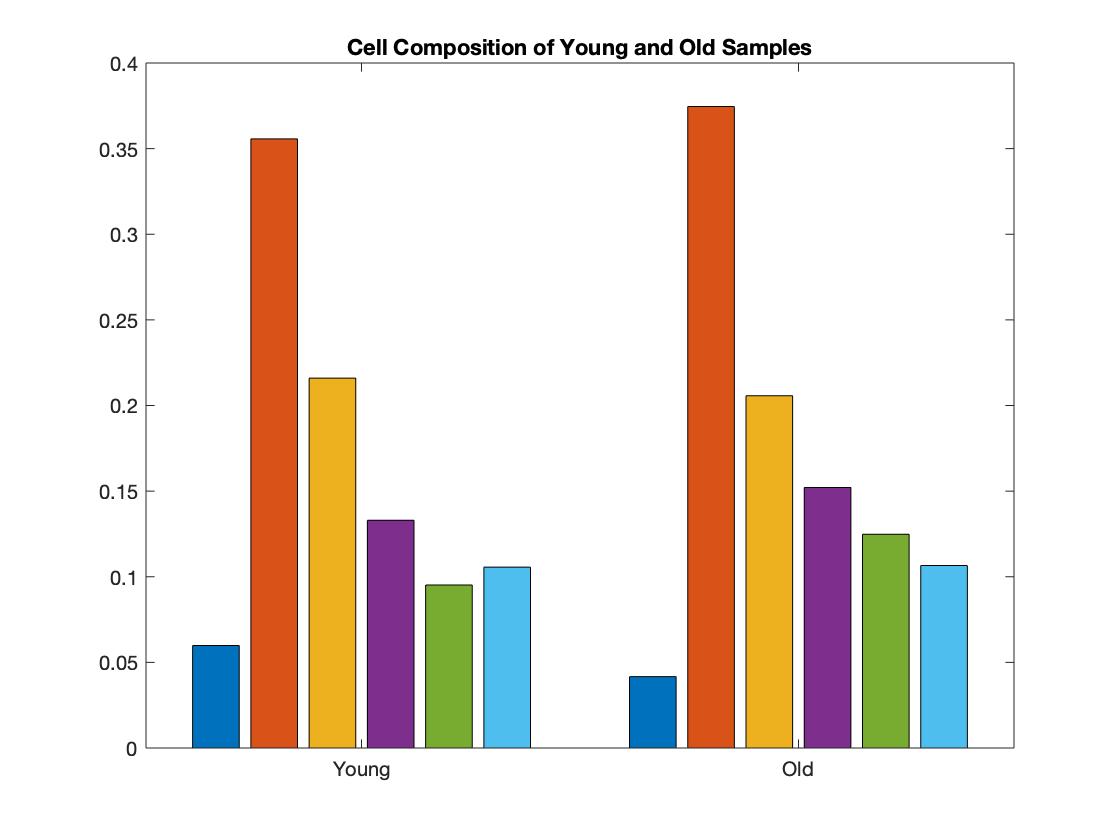


compY1 = [];
for i=1:6
new = younghist(i)./7166; %fix this
compY1 = [compY1, new];
end


compO1 = [];
for i=1:6
new = oldhist(i)./9471;
compO1 = [compO1, new];
end


% plot in bar graph
bar([compY1; compO1])
set(gca,'xticklabel', ["Young";"Old"])
%legend('OPC', 'OLG', 'ASC', 'mNEUR', 'EC', 'MG')
title('Cell Composition of Young and Old Samples')

% investigate statistical significance using Wilcox rank sum test

OPCY = [length(OPCindY1)/1370, length(OPCindY2)/1666, length(OPCindY3)/1851, length(OPCindY4)/2279];
OPCO = [length(OPCindO1)/1823, length(OPCindO2)/1489, length(OPCindO3)/3984, length(OPCindO4)/2175];

ECY = [length(ECindY1)/1370, length(ECindY2)/1666, length(ECindY3)/1851, length(ECindY4)/2279];
ECO = [length(ECindO1)/1823, length(ECindO2)/1489, length(ECindO3)/3984, length(ECindO4)/2175];


[p,h,stats] = ranksum(OPCY, OPCO)
[p,h,stats] = ranksum(ECY, ECO)



%Identifying age-related genes

%MG analysis

%calculate average gene expression for each cell type

p = 0.0286

h = logical
   1


stats = struct with fields:
    ranksum: 26


MGYavg = mean(genetableY(:,MGindY)');

p = 0.1143

h = logical
   0


stats = struct with fields:
    ranksum: 12


MGOavg = mean(genetableO(:,MGindO)');
%corrcoef(MGYavg, MGOavg)




%restricting to highly expressed genes
highMGO = MGOavg > .5;   % genes must be expressed above this level
highMGY = MGYavg > .5;
highExpMGY = MGYavg(highMGY');     %genes we found
highExpMGO = MGOavg(highMGY');      %these are the expression values
MGhighGenes = genelist(highMGY)     %these are the names


% identifying restricted genes w/ fold change above 10%
MGfoldchange = highExpMGO./highExpMGY;
MGindstouse = MGfoldchange > 1.1 | MGfoldchange < .909 & MGfoldchange ~= 0;

MGYdatatoUse = highExpMGY(MGindstouse)%gene expression values
MGOdatatoUse = highExpMGO(MGindstouse)
MGhighGenes = MGhighGenes(MGindstouse)    %gene names

MGhighGenes = 931×1 cell array
    {'Tram1'   }
    {'Rpl7'    }
    {'Tceb1'   }
    {'Ogfrl1'  }
    {'Ptpn18'  }
    {'Cox5b'   }
    {'Rpl31'   }
    {'Sf3b1'   }
    {'Hspe1'   }
    {'Ndufb3'  }
    {'Sumo1'   }
    {'Eef1b2'  }
    {'Rpl37a'  }
    {'Arpc2'   }
    {'Aamp'    }
    {'Slc11a1' }
    {'Serpine2'}
    {'Itm2c'   }
    {'Ncl'     }
    {'Ptma'    }
    {'Inpp5d'  }
    {'Myeov2'  }
    {'Dbi'     }
    {'Actr3'   }
    {'Srgap2'  }
    {'Btg2'    }
    {'Adipor1' }
    {'Cfh'     }
    {'Rgs2'    }
    {'Ivns1abp'}


MGfoldtoUse = MGOdatatoUse./MGYdatatoUse


% sort gene expression values
sorted = sort(MGfoldtoUse, "descend")

inds = [];

MGYdatatoUse =     0.6359    2.0590    0.5194    1.1571    2.0144    0.6038    0.7449    0.5081    0.9900    0.5136    0.5274    1.9440    0.7831    0.6173    0.5640    0.5675    0.7132    1.1684    0.6842    0.6726    0.7508    1.2882    0.7883    0.8359    0.8584    1.4072    1.4702    0.7450    0.5171    0.7220    0.7483    1.1514    0.6476    0.7560    0.6340    1.3254    1.3929    0.6686    0.5157    0.6652    0.9520    0.7791    1.6492    2.6734    0.6045    2.3827    1.2697    2.8490    0.6685    1.7656


for i = 1:length(MGfoldtoUse)                  %finding names of associated genes

MGOdatatoUse =     0.7531    2.5027    0.5825    1.2764    2.3442    0.6961    1.0489    0.5605    1.3790    0.6023    0.6403    2.1563    0.9994    0.6955    0.6858    0.6826    0.8231    1.3622    0.7626    0.6084    0.8395    1.5740    0.9101    1.0095    1.1260    2.0124    1.3275    0.8712    0.6752    0.8395    0.8486    1.3042    0.7229    0.8386    0.7125    1.5126    1.5669    0.7570    0.6483    0.5287    1.1719    0.8763    2.2269    2.3363    0.6849    2.8807    1.4876    3.1735    0.7781    2.0965


    new = find(MGfoldtoUse==sorted(1,i));

MGhighGenes = 398×1 cell array
    {'Tram1'  }
    {'Rpl7'   }
    {'Tceb1'  }
    {'Ptpn18' }
    {'Rpl31'  }
    {'Sf3b1'  }
    {'Hspe1'  }
    {'Ndufb3' }
    {'Eef1b2' }
    {'Slc11a1'}
    {'Ncl'    }
    {'Ptma'   }
    {'Dbi'    }
    {'Srgap2' }
    {'Adipor1'}
    {'Cfh'    }
    {'Arpc5'  }
    {'Creg1'  }
    {'Fcgr2b' }
    {'F11r'   }
    {'Cd84'   }
    {'H3f3a'  }
    {'Atp5c1' }
    {'Edf1'   }
    {'Rpl7a'  }
    {'Rpl12'  }
    {'Ptgs1'  }
    {'Zeb2'   }
    {'Nfe2l2' }
    {'Srp14'  }


    inds = [inds, new];

MGfoldtoUse =     1.1844    1.2155    1.1214    1.1031    1.1637    1.1529    1.4080    1.1030    1.3929    1.1727    1.2141    1.1092    1.2762    1.1268    1.2160    1.2029    1.1541    1.1659    1.1145    0.9046    1.1181    1.2219    1.1545    1.2077    1.3117    1.4301    0.9029    1.1695    1.3057    1.1628    1.1339    1.1327    1.1164    1.1093    1.1238    1.1412    1.1249    1.1322    1.2572    0.7949    1.2310    1.1248    1.3503    0.8739    1.1331    1.2090    1.1716    1.1139    1.1641    1.1874


end
orderedgenes = MGhighGenes(inds) 
highnames = orderedgenes(1:15)
lownames = orderedgenes(length(orderedgenes)-14:length(orderedgenes))

sorted =     1.6723    1.5801    1.5779    1.4301    1.4204    1.4201    1.4184    1.4080    1.4016    1.3929    1.3575    1.3515    1.3503    1.3412    1.3382    1.3306    1.3133    1.3132    1.3117    1.3057    1.3038    1.3018    1.2991    1.2987    1.2965    1.2965    1.2924    1.2903    1.2901    1.2872    1.2856    1.2843    1.2827    1.2826    1.2812    1.2767    1.2762    1.2750    1.2737    1.2714    1.2697    1.2672    1.2668    1.2633    1.2625    1.2600    1.2592    1.2590    1.2573    1.2572


names = cat(1,highnames,lownames)

% make a heatmap of top 15 highest and lowest expresseed genes
heatmapHi = sorted(1:15);
heatmapLow = sorted(length(sorted)-14:length(sorted));
heatmaptotal = cat(2,heatmapHi,heatmapLow);
heatmaptotal = log10(heatmaptotal)

orderedgenes = 398×1 cell array
    {'Rpl6'   }
    {'Klk8'   }
    {'PISD'   }
    {'Rpl12'  }
    {'Tmcc3'  }
    {'H2-K1'  }
    {'Lyz2'   }
    {'Hspe1'  }
    {'Herpud1'}
    {'Eef1b2' }
    {'Cd52'   }
    {'Akr1a1' }
    {'Rps21'  }
    {'Krtcap2'}
    {'Tpt1'   }
    {'Tmem14c'}
    {'Rpl5'   }
    {'Rpl15'  }
    {'Rpl7a'  }
    {'Nfe2l2' }
    {'Rpl30'  }
    {'Actr2'  }
    {'Rpl22'  }
    {'Srsf3'  }
    {'Gm10073'}
    {'Rps10'  }
    {'Gnb2l1' }
    {'Tomm7'  }
    {'Rer1'   }
    {'Rnf7'   }


h = heatmap(heatmaptotal')

highnames = 15×1 cell array
    {'Rpl6'   }
    {'Klk8'   }
    {'PISD'   }
    {'Rpl12'  }
    {'Tmcc3'  }
    {'H2-K1'  }
    {'Lyz2'   }
    {'Hspe1'  }
    {'Herpud1'}
    {'Eef1b2' }
    {'Cd52'   }
    {'Akr1a1' }
    {'Rps21'  }
    {'Krtcap2'}
    {'Tpt1'   }


title("Differential Gene Expression in MG with Age");

lownames = 15×1 cell array
    {'Ndrg2'    }
    {'Fam212a'  }
    {'Cebpb'    }
    {'Rpl13-ps3'}
    {'Mt3'      }
    {'Lyl1'     }
    {'Jund'     }
    {'Bin2'     }
    {'Basp1'    }
    {'Tm6sf1'   }
    {'Klf2'     }
    {'Dusp1'    }
    {'Cirbp'    }
    {'Ppp2ca'   }
    {'Pld1'     }


h.XDisplayLabels = {'MG'};

names = 30×1 cell array
    {'Rpl6'     }
    {'Klk8'     }
    {'PISD'     }
    {'Rpl12'    }
    {'Tmcc3'    }
    {'H2-K1'    }
    {'Lyz2'     }
    {'Hspe1'    }
    {'Herpud1'  }
    {'Eef1b2'   }
    {'Cd52'     }
    {'Akr1a1'   }
    {'Rps21'    }
    {'Krtcap2'  }
    {'Tpt1'     }
    {'Ndrg2'    }
    {'Fam212a'  }
    {'Cebpb'    }
    {'Rpl13-ps3'}
    {'Mt3'      }
    {'Lyl1'     }
    {'Jund'     }
    {'Bin2'     }
    {'Basp1'    }
    {'Tm6sf1'   }
    {'Klf2'     }
    {'Dusp1'    }
    {'Cirbp'    }
    {'Ppp2ca'   }
    {'Pld1'     }


h.YDisplayLabels = names;
h.ColorScaling = 'scaled';
h.Colormap = parula




heatmaptotal =     0.2233    0.1987    0.1981    0.1554    0.1524    0.1523    0.1518    0.1486    0.1466    0.1439    0.1327    0.1308    0.1304    0.1275    0.1265   -0.0888   -0.0900   -0.0997   -0.1001   -0.1102   -0.1181   -0.1189   -0.1212   -0.1284   -0.1300   -0.1349   -0.1358   -0.1413   -0.1646   -0.2079


find(orderedgenes == "Csf1r")

h =   HeatmapChart with properties:

        XData: {'1'}
        YData: {30×1 cell}
    ColorData: [30×1 double]

  Show all properties


find(genelist == "Ctss")


%dataToUse_MG = MGY1avg(indstouse)

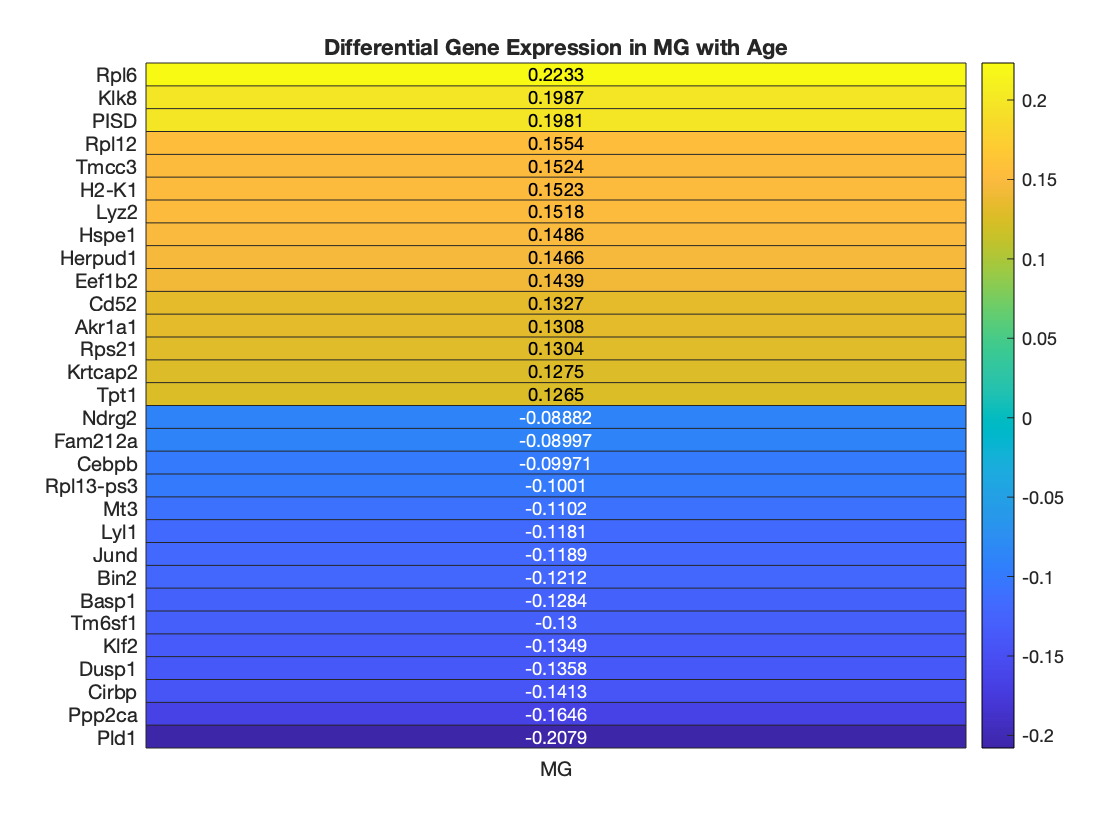

h =   HeatmapChart (Differential Gene Expression in MG with Age) with properties:

        XData: {'1'}
        YData: {30×1 cell}
    ColorData: [30×1 double]

  Show all properties


%Analysis of age-related gene changes across cell-types


%finding most up/downregulated genes across all cell types

%calculate average gene expression of each cell type

ans = 356

OPCYavg = mean(genetableY(:,OPCindY)');

ans = 2950

OPCOavg = mean(genetableO(:,OPCindO)');

OLGYavg = mean(genetableY(:,OLGindY)');
OLGOavg = mean(genetableO(:,OLGindO)');

ASCYavg = mean(genetableY(:,ASCindY)');
ASCOavg = mean(genetableO(:,ASCindO)');

mNEURYavg = mean(genetableY(:,mNEURindY)');
mNEUROavg = mean(genetableO(:,mNEURindO)');

ECYavg = mean(genetableY(:,ECindY)');
ECOavg = mean(genetableO(:,ECindO)');
%average gene expression for all cells
Yavg = [OPCYavg;OLGYavg;ASCYavg;mNEURYavg;ECYavg;MGYavg];
Oavg = [OPCOavg;OLGOavg;ASCOavg;mNEUROavg;ECOavg;MGOavg];
meanYavg = mean(Yavg);
meanOavg = mean(Oavg);



%restricting to highly expressed genes
highindO = meanOavg > .5;   % genes must be expressed above this level
highindY = meanYavg > .5;
highExpY = meanYavg(highindY);     %genes we found
highExpO = meanOavg(highindY);      %these are the expression values
highGenesAll = genelist(highindY)     %these are the names

TotalFoldChange = highExpO./highExpY    %this one doesn't



allsorted = sort(TotalFoldChange, 'ascend');


lowest1 = find(TotalFoldChange==allsorted(1,1));
lowest2 = find(TotalFoldChange==allsorted(1,2));

highGenesAll = 1002×1 cell array
    {'Rpl7'    }
    {'Tceb1'   }
    {'Ptp4a1'  }
    {'Cox5b'   }
    {'Rpl31'   }
    {'Pantr1'  }
    {'Sf3b1'   }
    {'Hspe1'   }
    {'Ndufb3'  }
    {'Sumo1'   }
    {'Eef1b2'  }
    {'Rpl37a'  }
    {'Arpc2'   }
    {'Aamp'    }
    {'Pnkd'    }
    {'Acsl3'   }
    {'Serpine2'}
    {'Mff'     }
    {'Itm2c'   }
    {'Ncl'     }
    {'Ptma'    }
    {'Ramp1'   }
    {'Ndufa10' }
    {'Myeov2'  }
    {'Fam174a' }
    {'Tsn'     }
    {'Dbi'     }
    {'Ccnt2'   }
    {'Nucks1'  }
    {'Adipor1' }


lowest3 = find(TotalFoldChange==allsorted(1,3));
highest1 = find(TotalFoldChange==allsorted(1,length(allsorted)-1));

TotalFoldChange =     1.1429    1.0198    1.0206    0.9855    1.1245    0.8769    1.0961    1.1953    1.0674    0.9514    1.1888    1.0577    1.0273    0.9661    1.0120    0.9402    0.9200    0.9518    0.9818    1.2101    1.0658    0.9414    0.9609    0.9709    0.9666    1.0356    1.0561    1.0182    1.0642    0.9240    0.8226    0.9809    0.9564    0.9545    1.0181    0.9984    1.0181    1.0184    1.0411    1.0455    1.0325    1.0488    1.1795    1.0471    1.0473    0.9299    0.9883    1.0098    1.0884    1.0024


highest2 = find(TotalFoldChange==allsorted(1,length(allsorted)-2));
highest3 = find(TotalFoldChange==allsorted(1,length(allsorted)-3));
highGenesAll(lowest1)
highGenesAll(lowest2)
highGenesAll(lowest3)
highGenesAll(highest1)
highGenesAll(highest2)
highGenesAll(highest3)


% genes to validate

% upregulated from paper
B2mind = find(genelist=="B2m");

ans = 1×1 cell array
    {'Basp1'}


Rpl6ind = find(genelist=="Rpl6");

ans = 1×1 cell array
    {'Rpl13-ps3'}


Malat1ind = find(genelist=="Malat1");

ans = 1×1 cell array
    {'Ppp2ca'}


ans = 1×1 cell array
    {'Rpl6'}


%downregulated from paper

ans = 1×1 cell array
    {'Rpl12'}


mtND1ind=find(genelist=="mt-Nd1");

ans = 1×1 cell array
    {'Ptges3'}


Aldocind=find(genelist=="Aldoc");
Sepw1ind=find(genelist=="Sepw1");

%traditional aging marker
Ctssind = find(genelist=="Ctss");

%newly discovered marker in paper
Apoc1ind = find(genelist=="Apoc1");
Calyind = find(genelist=="Caly");

%bidirectional genes
Cd9ind = find(genelist=="Cd9");
Rpl37aind = find(genelist=="Rpl37a");

%genes we found most up/downregulated
Basp1ind = find(genelist=="Basp1");
Rpl12ind = find(genelist=="Rpl12");




allfoldchange = Oavg./Yavg;
%find genes of interest
B2m = allfoldchange(:,B2mind);
Rpl6 = allfoldchange(:,Rpl6ind);
Malat1 = allfoldchange(:,Malat1ind);
mtND1 = allfoldchange(:,mtND1ind);
Aldoc = allfoldchange(:,Aldocind);
Sepw1 = allfoldchange(:,Sepw1ind);
Ctss = allfoldchange(:,Ctssind);
Caly = allfoldchange(:,Calyind);
Cd9 = allfoldchange(:,Cd9ind);
Rpl37a = allfoldchange(:,Rpl37aind);

highGenesAll = 1002×1 cell array
    {'Rpl7'    }
    {'Tceb1'   }
    {'Ptp4a1'  }
    {'Cox5b'   }
    {'Rpl31'   }
    {'Pantr1'  }
    {'Sf3b1'   }
    {'Hspe1'   }
    {'Ndufb3'  }
    {'Sumo1'   }
    {'Eef1b2'  }
    {'Rpl37a'  }
    {'Arpc2'   }
    {'Aamp'    }
    {'Pnkd'    }
    {'Acsl3'   }
    {'Serpine2'}
    {'Mff'     }
    {'Itm2c'   }
    {'Ncl'     }
    {'Ptma'    }
    {'Ramp1'   }
    {'Ndufa10' }
    {'Myeov2'  }
    {'Fam174a' }
    {'Tsn'     }
    {'Dbi'     }
    {'Ccnt2'   }
    {'Nucks1'  }
    {'Adipor1' }


TotalFoldChange =     1.1429    1.0198    1.0206    0.9855    1.1245    0.8769    1.0961    1.1953    1.0674    0.9514    1.1888    1.0577    1.0273    0.9661    1.0120    0.9402    0.9200    0.9518    0.9818    1.2101    1.0658    0.9414    0.9609    0.9709    0.9666    1.0356    1.0561    1.0182    1.0642    0.9240    0.8226    0.9809    0.9564    0.9545    1.0181    0.9984    1.0181    1.0184    1.0411    1.0455    1.0325    1.0488    1.1795    1.0471    1.0473    0.9299    0.9883    1.0098    1.0884    1.0024


ans = 1×1 cell array
    {'Basp1'}


ans = 1×1 cell array
    {'Rpl13-ps3'}


ans = 1×1 cell array
    {'Ppp2ca'}


ans = 1×1 cell array
    {'Rpl6'}


ans = 1×1 cell array
    {'Rpl12'}


ans = 1×1 cell array
    {'Ptges3'}


Basp1 = allfoldchange(:,Basp1ind);
Rpl12 = allfoldchange(:,Rpl12ind);

total = [B2m,Rpl6,Rpl12, Malat1, Ctss,Caly, mtND1,Aldoc,Sepw1, Cd9, Rpl37a,Basp1];
total = log10(total)
h2 = heatmap(total')
title("Validation of Selected Aging Signatures");
h2.XDisplayLabels = {'OPC','OLG','ASC','mNEUR','EC','MG'};
h2.YDisplayLabels = {'B2m', 'Rpl6','Rpl12','Malat1','Ctss','Caly','mt-Nd1','Aldoc','Sepw1','Cd9','Rpl37a','Basp1'};
h2.ColorScaling = 'scaled';
h2.Colormap = parula


genetableY1(high_indY1)
genetableO1(high_indO1)
MG_high = cat(2, genetableY1(high_indY1),genetableO1(high_indO1))
MG_Y1vsO1 = tsne(MG_high, "Algorithm","barneshut","NumPCAComponents",50)

total =     0.0739    0.1007    0.1107    0.0236    0.1321    0.0316   -0.0101    0.0326   -0.0303   -0.0510   -0.0181   -0.1720
    0.1627    0.1642    0.1178    0.0029    0.2893    0.0173   -0.0093   -0.0557   -0.0196   -0.0342    0.0230   -0.0430
    0.1053    0.1642    0.1062    0.0140    0.1890    0.1728   -0.0177   -0.0301   -0.0313   -0.0636    0.0204   -0.1074
    0.0534    0.1729    0.1235    0.0176    0.3916   -0.0032   -0.0220   -0.0572   -0.0178   -0.0731    0.0785   -0.0620
   -0.0137    0.0984    0.0753    0.0136    0.0760    0.0747   -0.0071   -0.0565   -0.0457    0.1340    0.0098   -0.0593
    0.0303    0.2233    0.1554    0.0051   -0.0129   -0.0829   -0.0218   -0.0379   -0.0272    0.0257    0.0353   -0.1284


h2 =   HeatmapChart with properties:

        XData: {6×1 cell}
        YData: {12×1 cell}
    ColorData: [12×6 double]

  Show all properties


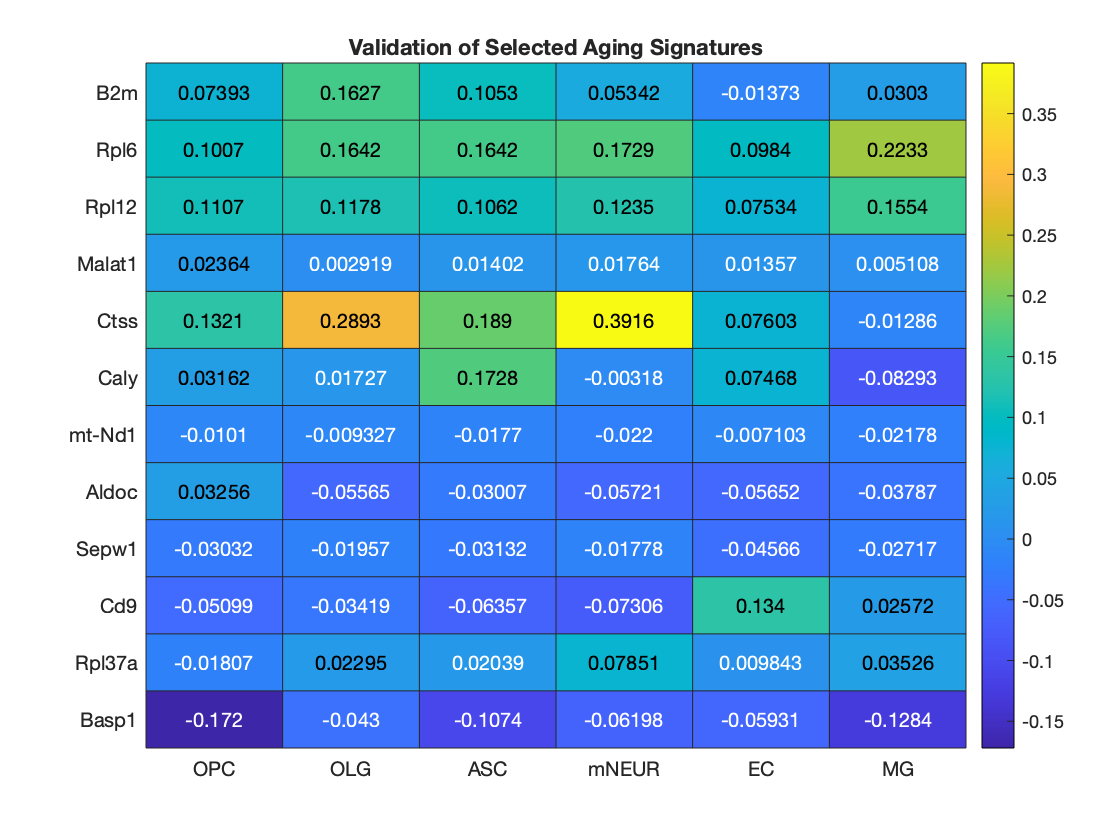

h2 =   HeatmapChart (Validation of Selected Aging Signatures) with properties:

        XData: {6×1 cell}
        YData: {12×1 cell}
    ColorData: [12×6 double]

  Show all properties


sce=SingleCellExperiment(genetableY1,genelist)
sc_scatter(sce);

remove = [];
counter = 0;

for column = 1:1371
    for row = 1:14699
        if genetable(row, column) > 0
            counter = counter + 1;
        end
    end

ans =     1.3403
    1.3403
    1.8931
    1.3403
    1.3403
    1.3403
    1.8931
    1.3403
    1.3403
    1.3403


    if counter < 250

ans =     1.9902
         0
         0
         0
    1.9902
    1.9902
         0
         0
    1.9902
         0


        remove = [remove, column];

Error using cat
Dimensions of arrays being concatenated are not consistent.

    end
    counter = 0;
end


sce =   SingleCellExperiment with properties:

                          X: [14699×1370 double]
                          g: [14699×1 string]
                          s: [1370×3 double]
                          c: [1370×1 double]
            c_cell_cycle_tx: []
             c_cell_type_tx: []
               c_cluster_id: []
                 c_batch_id: []
                  c_cell_id: [1370×1 double]
       list_cell_attributes: {}
       list_gene_attributes: {}
     struct_cell_embeddings: [1×1 struct]
    struct_cell_clusterings: [1×1 struct]
           table_attributes: [0×0 table]
                   NumCells: 1370
                   NumGenes: 14699


processed = genetable;

Error using uipushtool
First argument must be a valid parent, such as a Figure or Panel object.

Error in sc_scatter_sce/i_addbutton (line 86)
        pt3 = uipushtool(barhandle, 'Separator', septag);

Error in sc_scatter_sce (

for i = 1:323
    processed(:, remove(1,i)) = [];
end